# Furuta Pendulum - Multiple Pulse Tests

## 1. Pulse Cases

Test the three accepted controllers with positive and negative arm-torque pulses. Change amplitude and duration while keeping the actuator cap and run time fixed. Each row is a separate fresh simulation, not a pulse train. The long weak pulse has the same impulse as the nominal pulse, but a different shape.

assert(isfolder('data')&&isfolder('models'),'Set Current Folder to Furuta_Clean_Project.');
addpath('models','geometry');
Case=["Small positive";"Small negative";"Nominal positive";"Nominal negative"; ...
    "Short strong positive";"Short strong negative";"Strong positive";"Strong negative"; ...
    "Long weak positive";"Long weak negative"];
Amplitude_Nm=[0.005;-0.005;0.01;-0.01;0.02;-0.02;0.02;-0.02;0.005;-0.005];
Width_s=[0.05;0.05;0.05;0.05;0.02;0.02;0.05;0.05;0.10;0.10];
On_s=ones(10,1);Off_s=On_s+Width_s;
Impulse_Nm_s=Amplitude_Nm.*Width_s;
pulse_cases=table(Case,Amplitude_Nm,Width_s,On_s,Off_s,Impulse_Nm_s)

pulse_cases = 10×6 table
             Case              Amplitude_Nm    Width_s    On_s    Off_s    Impulse_Nm_s
    _______________________    ____________    _______    ____    _____    ____________

    "Small positive"               0.005        0.05       1      1.05        0.00025  
    "Small negative"              -0.005        0.05       1      1.05       -0.00025  
    "Nominal positive"              0.01        0.05       1      1.05         0.0005  
    "Nominal negative"             -0.01        0.05       1      1.05        -0.0005  
    "Short strong positive"         0.02        0.02       1      1.02         0.0004  
    "Short strong negative"        -0.02        0.02       1      1.02        -0.0004  
    "Strong positive"               0.02        0.05       1      

actuator_limit=0.01;run_time=10;


## 2. Fixed Accepted Controllers

Use the accepted PID gains, pole set and LQR weights. This is a robustness test, not a tuning search. No candidate gains are selected and no accepted gain file is overwritten. The saved plant is copied before the tests; open model edits are not included or changed.

load('data/Linear_Model_Data.mat');
load('data/Accepted_Controller_Data.mat');
Kpp=place(A,B,[-5,-6,-8,-10]);
Klqr=lqr(A,B,Q,Rcost);
assert(norm(Kpp-K_pp)<1e-7 && norm(Klqr-K_lqr)<1e-7);
accepted_design=struct('PID',PID,'Kpp',Kpp,'Klqr',Klqr, ...
    'Q',Q,'R',Rcost,'A',A,'B',B,'xe',x_equilibrium,'taue',tau_equilibrium);


## 3. Run the Nonlinear Pulse Sweep

Run all ten pulse cases for each controller: 30 nonlinear Multibody simulations. The local function sets the actual pulse edges, amplitudes, cap, equilibrium and gains for every run. A progress CSV is updated after each trial. Failed simulations are recorded, not hidden.

[pulse_results,pulse_runs]=run_pulse_sweep(pulse_cases,accepted_design,actuator_limit,run_time);

Pulse sweep 1/30 | Small positive | PID | peak 1.382 deg | arm settling 5.53 s
Pulse sweep 2/30 | Small positive | Pole Placement | peak 1.526 deg | arm settling 1.17 s
Pulse sweep 3/30 | Small positive | LQR | peak 1.337 deg | arm settling 1.24 s
Pulse sweep 4/30 | Small negative | PID | peak 1.382 deg | arm settling 5.54 s
Pulse sweep 5/30 | Small negative | Pole Placement | peak 1.526 deg | arm settling 1.17 s
Pulse sweep 6/30 | Small negative | LQR | peak 1.337 deg | arm settling 1.24 s
Pulse sweep 7/30 | Nominal positive | PID | peak 2.765 deg | arm settling 6.91 s
Pulse sweep 8/30 | Nominal positive | Pole Placement | peak 3.054 deg | arm settling 1.34 s
Pulse sweep 9/30 | Nominal positive | LQR | peak 2.675 deg | arm settling 1.37 s
Pulse sweep 10/30 | Nominal negative | PID | peak 2.765 deg | arm settling 6.91 s
Pulse sweep 11/30 | Nominal negative | Pole Placement | peak 3.054 deg | arm settling 1.34 s
Pulse sweep 12/30 | Nominal negative | LQR | peak 2.675 deg | arm settling 

save('results/Pulse_Sweep.mat','pulse_results','pulse_runs','pulse_cases', ...
    'accepted_design','actuator_limit','run_time','-v7.3');
writetable(pulse_results,'results/Pulse_Sweep.csv');
disp('All pulse-sweep trials attempted.');

All pulse-sweep trials attempted.


## 4. Performance and Recovery

Settling starts after each pulse ends. The bands are +/-0.1 deg for the pendulum and +/-1 deg for the arm. Inf means that the state did not settle within the ten-second run. ReturnedToBands reports finite settling for both angles; MeetsTestTargets also applies the stated peak, settling and effort targets. A missed target is not by itself proof of instability.

pulse_results(:,{'Case','Controller','Amplitude_Nm','Width_s', ...
    'PeakPendulum_deg','PeakArm_deg','PendulumSettling_s','ArmSettling_s', ...
    'PeakTorque_Nm','SaturationFraction','ReturnedToBands','MeetsTestTargets','Completed'})

ans = 30×13 table
             Case                 Controller       Amplitude_Nm    Width_s    PeakPendulum_deg    PeakArm_deg    PendulumSettling_s    ArmSettling_s    PeakTorque_Nm    SaturationFraction    ReturnedToBands    MeetsTestTargets    Completed
    _______________________    ________________    ____________    _______    ________________    ___________    __________________    _____________    _____________    __________________    _______________    ________________    _________

    "Small positive"           "PID"                   0.00

% Nominal-impulse tests: peak pendulum <=8 deg, settling <=2.5 s,
% arm settling <=8 s, peak actuator torque <=0.0095 N m, no saturation.
% Strong-impulse tests: peak pendulum <=20 deg, settling <=5 s,
% arm settling <=9 s, final pendulum error <=0.01 deg.
% Strong tests may saturate. Mechanical arm-travel limits are not modelled.


## 5. Compare Pulse Responses

Each panel compares all three controllers for one pulse. Positive and negative pulses are shown in separate figures to keep the plots readable. The input acts at the arm joint, after actuator saturation; total joint torque can therefore exceed the actuator cap.

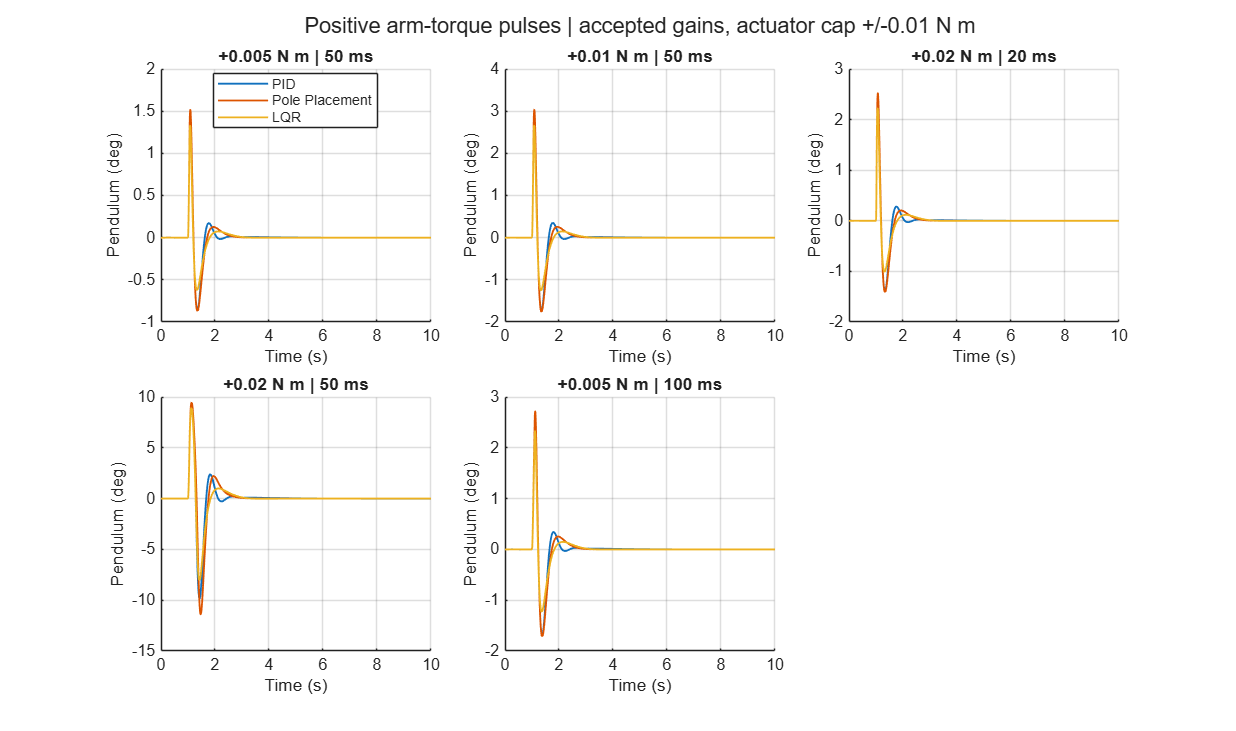

plot_pulse_cases(pulse_cases,pulse_runs,1,'Positive');
drawnow;exportgraphics(gcf,'results/Pulse_Sweep_Positive.png','Resolution',140);

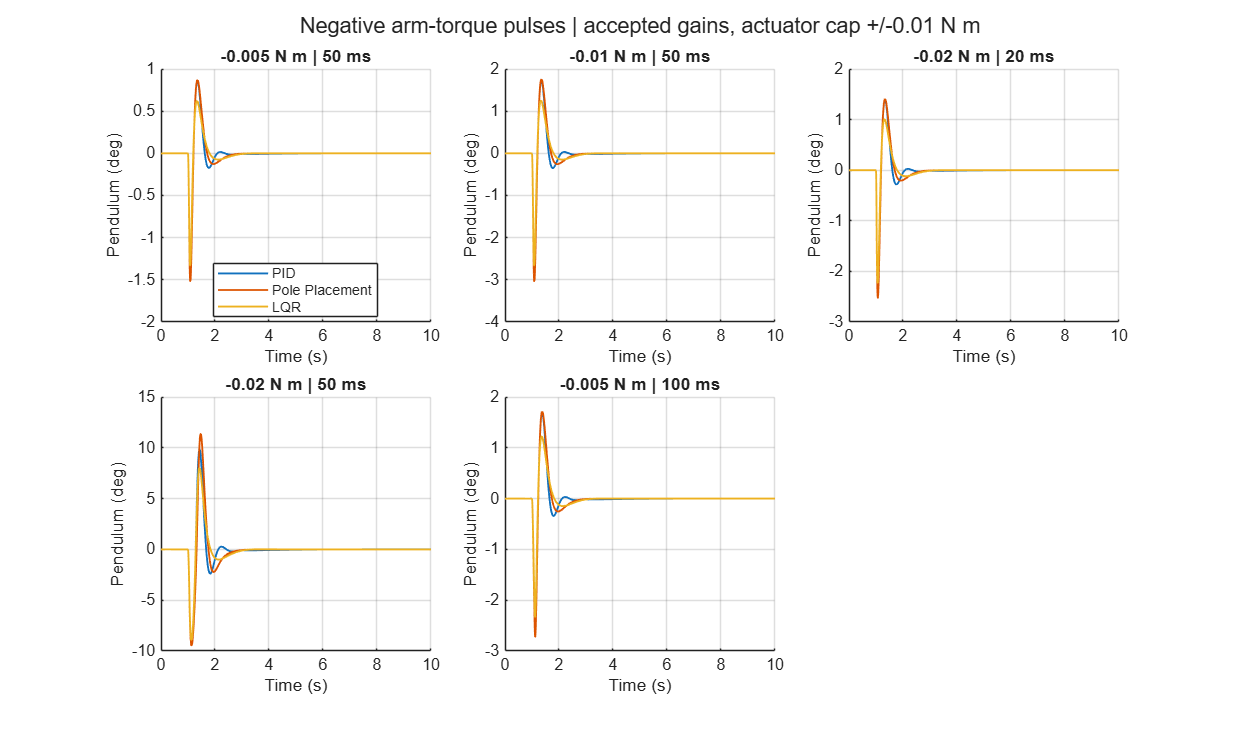

plot_pulse_cases(pulse_cases,pulse_runs,-1,'Negative');
drawnow;exportgraphics(gcf,'results/Pulse_Sweep_Negative.png','Resolution',140);

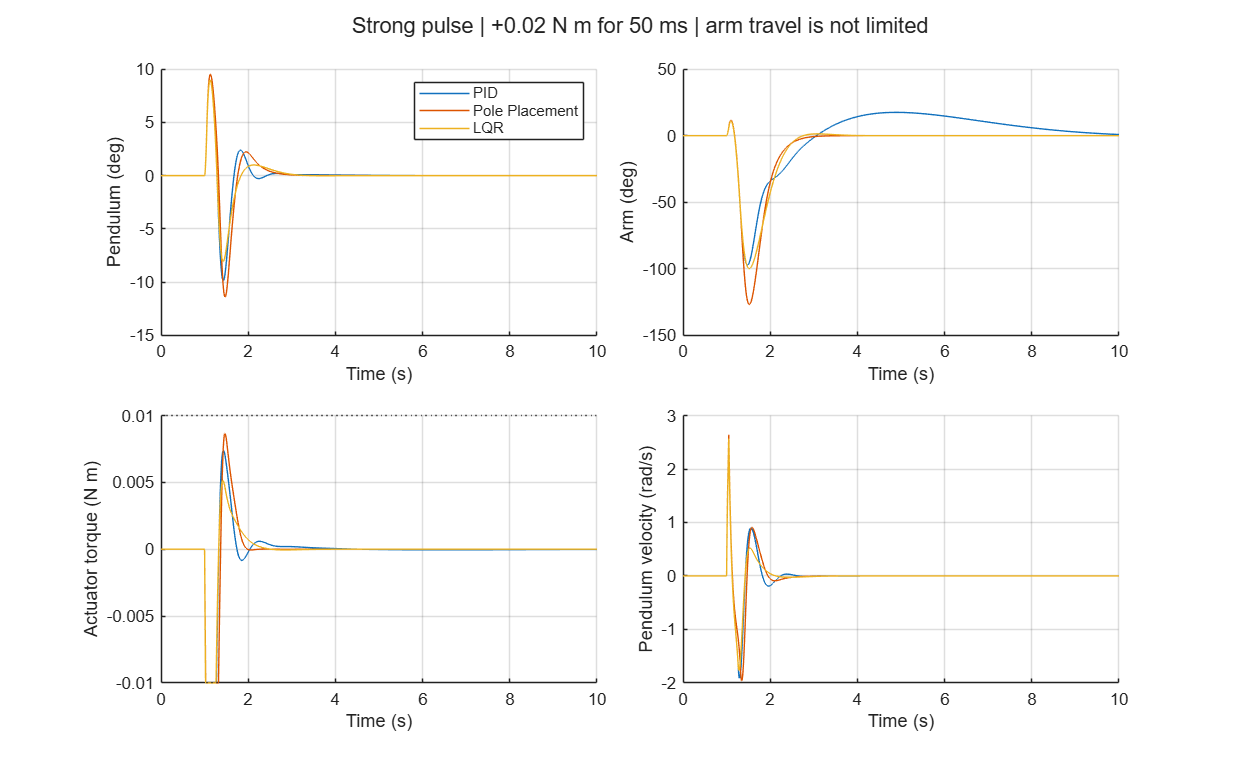

plot_strong_case(pulse_runs,pulse_cases);
drawnow;exportgraphics(gcf,'results/Pulse_Sweep_Strong_Detail.png','Resolution',140);

## 6. Summary Across the Tested Pulses

Compare the worst recorded excursion, recovery time and saturation for each controller. Read the individual case rows before choosing a controller. A lower nominal score does not guarantee better performance for every pulse shape.

controllers=["PID";"Pole Placement";"LQR"];sweep_summary=table;
for k=1:3
    rows=pulse_results(pulse_results.Controller==controllers(k),:);
    row=table(controllers(k),sum(rows.Completed),sum(rows.ReturnedToBands), ...
        sum(rows.MeetsTestTargets),max(rows.PeakPendulum_deg),max(rows.PeakArm_deg), ...
        max(rows.PendulumSettling_s),max(rows.ArmSettling_s),max(rows.SaturationFraction), ...
        'VariableNames',{'Controller','CompletedRuns','RecoveredRuns','TargetPasses', ...
        'WorstPendulum_deg','WorstArm_deg','WorstPendulumSettling_s', ...
        'WorstArmSettling_s','WorstSaturationFraction'});
    sweep_summary=[sweep_summary;row];
end
sweep_summary

sweep_summary = 3×9 table
       Controller       CompletedRuns    RecoveredRuns    TargetPasses    WorstPendulum_deg    WorstArm_deg    WorstPendulumSettling_s    WorstArmSettling_s    WorstSaturationFraction
    ________________    _____________    _____________    ____________    _________________    ____________    _______________________    __________________    _______________________

    "PID"                    10               10               10              9.8792             97.256                1.951                    8.86                   0.0248         
    "Pole Placement"         10               10               10              11.404              126.9           

save('results/Pulse_Sweep_Summary.mat','sweep_summary');
writetable(sweep_summary,'results/Pulse_Sweep_Summary.csv');


## 7. Interpretation and Limits

These results apply to the saved model, fixed accepted gains and the ten listed arm-torque pulses. They are not hardware tests or a proof for every disturbance. Equal impulse does not imply identical response in a coupled nonlinear system with torque limits. Constant loads, initial tilt, pulse trains, sensor noise and parameter uncertainty are separate tests. No tuning or gain replacement is performed here.

fprintf('Completed simulations: %d of %d.\n',sum(pulse_results.Completed),height(pulse_results));

Completed simulations: 30 of 30.


fprintf('Returned to both bands within the run: %d of %d.\n', ...
    sum(pulse_results.ReturnedToBands),height(pulse_results));

Returned to both bands within the run: 30 of 30.


save('results/Pulse_Sweep_Checked.mat','sweep_summary','pulse_cases');


## Local Functions

These functions run the temporary plant, measure each trial and draw the comparisons. They are part of this Live Script.

function [results,runs]=run_pulse_sweep(cases,design,limit,stopTime)
assert(~bdIsLoaded('Furuta_Pulse_Sweep_Run'),'Close the earlier temporary pulse-sweep model first.');
folder=tempname;mkdir(folder);model='Furuta_Pulse_Sweep_Run';
source=fullfile(pwd,'models','Furuta_StudyF.slx');
copyfile(source,fullfile(folder,[model '.slx']));
copyfile(source,'results/Pulse_Sweep_Model_Snapshot.slx');
load_system(fullfile(folder,[model '.slx']));
cleanup=onCleanup(@()close_system(model,0));
names={'PID','Pole Placement','LQR'};runs=cell(height(cases),3);results=table;
for c=1:height(cases)
    for k=1:3
        in=Simulink.SimulationInput(model);
        in=in.setModelParameter('StopTime',num2str(stopTime,17));
        in=in.setBlockParameter([model '/Measured states'],'OpenAtSimulationStart','off');
        in=in.setBlockParameter([model '/Applied torque Nm'],'OpenAtSimulationStart','off');
        in=in.setBlockParameter([model '/Controller selector'],'controller_choice',names{k});
        in=in.setBlockParameter([model '/Pulse starts'],'Time',num2str(cases.On_s(c),17));
        in=in.setBlockParameter([model '/Pulse starts'],'Before','0');
        in=in.setBlockParameter([model '/Pulse starts'],'After',num2str(cases.Amplitude_Nm(c),17));
        in=in.setBlockParameter([model '/Pulse ends'],'Time',num2str(cases.Off_s(c),17));
        in=in.setBlockParameter([model '/Pulse ends'],'Before','0');
        in=in.setBlockParameter([model '/Pulse ends'],'After',num2str(-cases.Amplitude_Nm(c),17));
        in=in.setVariable('tau_limit_sim',limit,'Workspace',model);
        in=in.setVariable('xe_controller',design.xe,'Workspace',model);
        in=in.setVariable('taue_controller',design.taue,'Workspace',model);
        if k==1
            fields={'ArmP','ArmI','ArmD','PendP','PendD'};
            for j=1:numel(fields)
                in=in.setVariable(['pid_' fields{j}],design.PID.(fields{j}),'Workspace',model);
            end
        elseif k==2
            in=in.setVariable('K_pp_controller',design.Kpp,'Workspace',model);
        else
            in=in.setVariable('K_lqr_controller',design.Klqr,'Workspace',model);
        end
        row=empty_row(cases(c,:),names{k});
        try
            raw=sim(in);xs=raw.x_simscape;us=raw.tau_controller;
            assert(xs.Time(end)>=stopTime-1e-8 && us.Time(end)>=stopTime-1e-8, ...
                'Simulation stopped before the requested end time.');
            t=(0:0.001:stopTime)';
            [tx,ix]=unique(xs.Time);[tu,iu]=unique(us.Time);
            x=interp1(tx,xs.Data(ix,:),t,'pchip')-design.xe';
            u=interp1(tu,us.Data(iu,:),t,'pchip');
            assert(all(isfinite(x(:)))&&all(isfinite(u)),'Incomplete or non-finite output.');
            row=measure_row(row,t,x,u,cases.Off_s(c),limit);
            runs{c,k}=struct('t',t,'x',x,'u',u,'Case',cases(c,:),'Controller',names{k});
        catch e
            row.ErrorMessage=string(e.message);
        end
        results=[results;struct2table(row)];
        writetable(results,'results/Pulse_Sweep_Progress.csv');
        fprintf('Pulse sweep %d/30 | %s | %s | peak %.3f deg | arm settling %.3g s\n', ...
            height(results),char(cases.Case(c)),names{k},row.PeakPendulum_deg,row.ArmSettling_s);
    end
end
end

function row=empty_row(test,controller)
row=struct('Case',test.Case,'Controller',string(controller), ...
    'Amplitude_Nm',test.Amplitude_Nm,'Width_s',test.Width_s, ...
    'Impulse_Nm_s',test.Impulse_Nm_s,'PeakPendulum_deg',NaN,'PeakArm_deg',NaN, ...
    'PendulumSettling_s',Inf,'ArmSettling_s',Inf,'PeakTorque_Nm',NaN, ...
    'RmsTorque_Nm',NaN,'SaturationFraction',NaN,'PendulumIAE_rad_s',NaN, ...
    'FinalPendulum_deg',NaN,'FinalArm_deg',NaN,'ReturnedToBands',false, ...
    'MeetsTestTargets',false,'Completed',false,'ErrorMessage',"");
end

function row=measure_row(row,t,x,u,pulseEnd,limit)
row.PeakPendulum_deg=max(abs(rad2deg(x(:,2))));
row.PeakArm_deg=max(abs(rad2deg(x(:,1))));
row.PendulumSettling_s=settle(t,x(:,2),deg2rad(0.1),pulseEnd);
row.ArmSettling_s=settle(t,x(:,1),deg2rad(1),pulseEnd);
row.PeakTorque_Nm=max(abs(u));
row.RmsTorque_Nm=sqrt(trapz(t,u.^2)/(t(end)-t(1)));
row.SaturationFraction=trapz(t,double(abs(u)>=limit*(1-1e-6)))/(t(end)-t(1));
row.PendulumIAE_rad_s=trapz(t,abs(x(:,2)));
row.FinalPendulum_deg=rad2deg(x(end,2));row.FinalArm_deg=rad2deg(x(end,1));
row.ReturnedToBands=isfinite(row.PendulumSettling_s)&&isfinite(row.ArmSettling_s);
if abs(row.Impulse_Nm_s)<=0.0005*(1+1e-9)
    row.MeetsTestTargets=row.PeakPendulum_deg<=8 && row.PeakArm_deg<=90 ...
        && row.PendulumSettling_s<=2.5 && row.ArmSettling_s<=8 ...
        && row.PeakTorque_Nm<=0.95*limit && row.SaturationFraction==0;
else
    row.MeetsTestTargets=row.PeakPendulum_deg<=20 && row.PendulumSettling_s<=5 ...
        && row.ArmSettling_s<=9 && abs(row.FinalPendulum_deg)<=0.01;
end
row.Completed=true;
end

function value=settle(t,y,band,start)
outside=find(t>=start & abs(y)>band);
if isempty(outside),value=0;
elseif outside(end)==numel(t),value=Inf;
else,value=t(outside(end)+1)-start;
end
end

function plot_pulse_cases(cases,runs,signValue,label)
indices=find(sign(cases.Amplitude_Nm)==signValue);
figure('Name',[label ' pulse comparisons'],'Color','w','Position',[60 60 1150 680]);
tiledlayout(2,3,'TileSpacing','compact');
for j=1:numel(indices)
    c=indices(j);nexttile;hold on;
    for k=1:3
        r=runs{c,k};
        if ~isempty(r),plot(r.t,rad2deg(r.x(:,2)),'LineWidth',1.1);end
    end
    title(sprintf('%+.3g N m | %.0f ms',cases.Amplitude_Nm(c),cases.Width_s(c)*1000));
    xlabel('Time (s)');ylabel('Pendulum (deg)');grid on;
    if j==1,legend('PID','Pole Placement','LQR','Location','best');end
end
sgtitle([label ' arm-torque pulses | accepted gains, actuator cap +/-0.01 N m']);
end

function plot_strong_case(runs,cases)
c=find(cases.Amplitude_Nm==0.02 & abs(cases.Width_s-0.05)<1e-9,1);
figure('Name','Strong pulse detail','Color','w','Position',[80 80 1000 620]);
tiledlayout(2,2,'TileSpacing','compact');
for k=1:3
    r=runs{c,k};if isempty(r),continue,end
    nexttile(1);hold on;plot(r.t,rad2deg(r.x(:,2)));
    nexttile(2);hold on;plot(r.t,rad2deg(r.x(:,1)));
    nexttile(3);hold on;plot(r.t,r.u);
    nexttile(4);hold on;plot(r.t,r.x(:,4));
end
nexttile(1);grid on;xlabel('Time (s)');ylabel('Pendulum (deg)');legend('PID','Pole Placement','LQR');
nexttile(2);grid on;xlabel('Time (s)');ylabel('Arm (deg)');
nexttile(3);grid on;xlabel('Time (s)');ylabel('Actuator torque (N m)');yline(0.01,':');yline(-0.01,':');
nexttile(4);grid on;xlabel('Time (s)');ylabel('Pendulum velocity (rad/s)');
sgtitle('Strong pulse | +0.02 N m for 50 ms | arm travel is not limited');
end
